# MEOW Data Analysis

clear;
clc;
close all;
dbstop if error;
subj_id = 501;
base_dir = '..';
subj_folder = sprintf('sub%03d', subj_id); 
results_dir = fullfile(base_dir, 'data', subj_folder);
concat_file = fullfile(results_dir, sprintf('sub%03d_concat.mat', subj_id));
rec_file = fullfile(results_dir, sprintf('sub%03d_rec.mat', subj_id)); 

load(concat_file, 'final_data_output');
load(rec_file, 'results_recognition');

MIN_RT_CUTOFF = 0.150;

subj_stats = [];
results_1_back = final_data_output.results_1_back;
results_2_back = final_data_output.results_2_back;

% define standard colors and fonts
plot_font_name = 'Helvetica';
plot_font_size_axis = 12;
plot_font_size_title = 14;
plot_color_comp = [0.1 0.4 0.7]; % dark blue
plot_color_iso  = [0.5 0.7 0.9]; % light blue
plot_color_nov  = [0.7 0.7 0.7]; % grey
plot_color_similar = [87, 46, 140] / 255;  % dark purple
plot_color_same = [173, 153, 189] / 255; % light purple
plot_color_new = [0.8 0.8 0.8];          % light grey
plot_color_a = plot_color_same;
plot_color_b = plot_color_similar;
plot_color_far = [1 1 1];

## 1-back

#### Calculation

results_1_back.corr_resp = cellstr(results_1_back.corr_resp);
results_1_back.resp_key = cellstr(results_1_back.resp_key);
na_idx = strcmp(results_1_back.resp_key, 'NA');
results_1_back.resp_key(na_idx) = {'none'};
results_1_back.correct = strcmp(results_1_back.corr_resp, results_1_back.resp_key);

% overall accuracy
subj_stats.oneback.overall_acc = mean(results_1_back.correct);

% 'compared' trials
comp_A_idx = (results_1_back.condition == "compared" & results_1_back.identity == "A");
comp_B_idx = (results_1_back.condition == "compared" & results_1_back.identity == "B");

% 'isolated' trials
iso_A_idx = (results_1_back.condition == "isolated" & results_1_back.identity == "A");
iso_B_idx = (results_1_back.condition == "isolated" & results_1_back.identity == "B");

% 'repeat' trials
rep_A1_idx = (results_1_back.condition == "repeat" & strcmp(results_1_back.corr_resp, 'none'));
rep_A2_idx = (results_1_back.condition == "repeat" & strcmp(results_1_back.corr_resp, 'j'));

subj_stats.oneback.acc_hit_similar = mean(results_1_back.correct(comp_B_idx));

% accuracy: "same" hit (correctly press 'j' for 2nd repeat 'A')
subj_stats.oneback.acc_hit_same = mean(results_1_back.correct(rep_A2_idx));

% accuracy: "correct rejection" trials (where 'none' is required)
all_cr_trials_idx = comp_A_idx | iso_A_idx | iso_B_idx | rep_A1_idx;
subj_stats.oneback.acc_cr_new = mean(results_1_back.correct(all_cr_trials_idx));

subj_stats.oneback.fa_new = 1 - subj_stats.oneback.acc_cr_new;

% RT
valid_rt_idx = results_1_back.rt > MIN_RT_CUTOFF;

% median rt for correct "similar" hits
subj_stats.oneback.rt_hit_similar = median(results_1_back.rt(...
    comp_B_idx & ...
    results_1_back.correct == 1 & ...
    valid_rt_idx), 'omitnan');

% median rt for correct "same" hits
subj_stats.oneback.rt_hit_same = median(results_1_back.rt(...
    rep_A2_idx & ...
    results_1_back.correct == 1 & ...
    valid_rt_idx), 'omitnan');

% 'compared B' trials (correct = 'k')
n_comp_B = sum(comp_B_idx);
subj_stats.oneback.err_comp_as_same = sum(strcmp(results_1_back.resp_key(comp_B_idx), 'j')) / n_comp_B;
subj_stats.oneback.err_comp_as_new = sum(strcmp(results_1_back.resp_key(comp_B_idx), 'none')) / n_comp_B;

% 'repeat A2' trials (correct = 'j')
n_rep_A2 = sum(rep_A2_idx);
subj_stats.oneback.err_rep_as_similar = sum(strcmp(results_1_back.resp_key(rep_A2_idx), 'k')) / n_rep_A2;
subj_stats.oneback.err_rep_as_new = sum(strcmp(results_1_back.resp_key(rep_A2_idx), 'none')) / n_rep_A2;

% 'new' trials (correct = 'none')
n_cr_new = sum(all_cr_trials_idx);
subj_stats.oneback.err_new_as_same = sum(strcmp(results_1_back.resp_key(all_cr_trials_idx), 'j')) / n_cr_new;
subj_stats.oneback.err_new_as_similar = sum(strcmp(results_1_back.resp_key(all_cr_trials_idx), 'k')) / n_cr_new;

% print
fprintf('overall accuracy: %f\n', subj_stats.oneback.overall_acc);

overall accuracy: 0.908333


fprintf('accuracy hit-same: %f\n', subj_stats.oneback.acc_hit_same);

accuracy hit-same: 0.841667


fprintf('accuracy hit-similar: %f\n', subj_stats.oneback.acc_hit_similar);

accuracy hit-similar: 0.758333


fprintf('accuracy cr: %f\n', subj_stats.oneback.acc_cr_new);

accuracy cr: 0.962500


fprintf('FAR new: %f\n', subj_stats.oneback.fa_new);

FAR new: 0.037500


fprintf('median rt hit-same: %f\n', subj_stats.oneback.rt_hit_same);

median rt hit-same: 0.875205


fprintf('median rt hit-similar: %f\n', subj_stats.oneback.rt_hit_similar);

median rt hit-similar: 0.889845


fprintf('compared lure error (as ''same''):  %.3f\n', subj_stats.oneback.err_comp_as_same);

compared lure error (as 'same'):  0.058


fprintf('compared lure error (as ''new''):   %.3f\n', subj_stats.oneback.err_comp_as_new);

compared lure error (as 'new'):   0.183


fprintf('repeat target error (as ''similar''): %.3f\n', subj_stats.oneback.err_rep_as_similar);

repeat target error (as 'similar'): 0.042


fprintf('repeat target error (as ''new''):     %.3f\n', subj_stats.oneback.err_rep_as_new);

repeat target error (as 'new'):     0.117


fprintf('new item error (as ''same''):       %.3f\n', subj_stats.oneback.err_new_as_same);

new item error (as 'same'):       0.019


fprintf('new item error (as ''similar''):    %.3f\n', subj_stats.oneback.err_new_as_similar);

new item error (as 'similar'):    0.019


### Plots. 1-Back

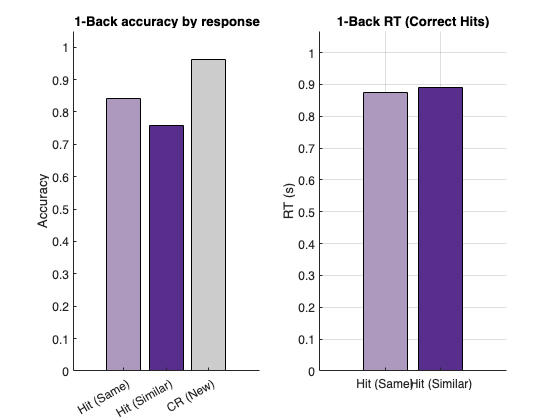

% 1-Back accuracy by response type
figure('color', 'white'); 
h_ax1 = subplot(1, 2, 1);
acc_data = [subj_stats.oneback.acc_hit_same, subj_stats.oneback.acc_hit_similar, subj_stats.oneback.acc_cr_new];
b1 = bar(acc_data, 'FaceColor', 'flat');
b1.CData(1,:) = plot_color_same;
b1.CData(2,:) = plot_color_similar;
b1.CData(3,:) = plot_color_new;

grid off;
box off;
title('1-Back accuracy by response', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('Accuracy', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax1, 'XTickLabel', {'Hit (Same)', 'Hit (Similar)', 'CR (New)'}, 'FontName', 'Helvetica', 'FontSize', plot_font_size_axis);
ylim([0, 1.05]);

% 1-Back RT by response type
h_ax2 = subplot(1, 2, 2);
rt_data = [subj_stats.oneback.rt_hit_same, subj_stats.oneback.rt_hit_similar];
b2 = bar(rt_data, 'FaceColor', 'flat');
b2.CData(1,:) = plot_color_same;
b2.CData(2,:) = plot_color_similar;

grid on;
box off;
title('1-Back RT (Correct Hits)', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('RT (s)', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax2, 'XTickLabel', {'Hit (Same)', 'Hit (Similar)'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
if all(~isnan(rt_data)), ylim([0, max(rt_data) * 1.2]); end

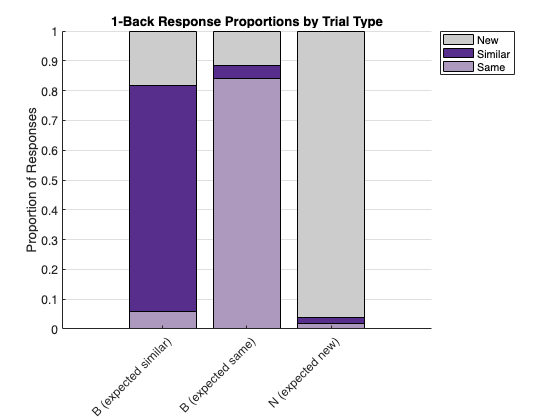


% 1-Back response proportions (incorrect trials)
figure('color', 'white');
plot_data = [
    subj_stats.oneback.err_comp_as_same, subj_stats.oneback.acc_hit_similar, subj_stats.oneback.err_comp_as_new; ...
    subj_stats.oneback.acc_hit_same, subj_stats.oneback.err_rep_as_similar, subj_stats.oneback.err_rep_as_new; ...
    subj_stats.oneback.err_new_as_same, subj_stats.oneback.err_new_as_similar, subj_stats.oneback.acc_cr_new ...
];
b_stack = bar(plot_data, 'stacked');
b_stack(1).FaceColor = plot_color_same;  
b_stack(2).FaceColor = plot_color_similar; 
b_stack(3).FaceColor = plot_color_new;  

box off;
grid on;
title('1-Back Response Proportions by Trial Type', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('Proportion of Responses', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
h_ax = gca;
set(h_ax, 'XTickLabel', {'B (expected similar)', 'B (expected same)', 'N (expected new)'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
xtickangle(h_ax, 45);
legend({'Same', 'Similar', 'New'}, 'Location', 'bestoutside','FontName', plot_font_name);
ylim([0, 1.0]);

## 2-back

#### Calculation

results_2_back.corr_resp = cellstr(results_2_back.corr_resp);
results_2_back.resp_key = cellstr(results_2_back.resp_key);
na_idx = strcmp(results_2_back.resp_key, 'NA');
results_2_back.resp_key(na_idx) = {'none'};
results_2_back.correct = strcmp(results_2_back.corr_resp, results_2_back.resp_key);

% overall accuracy
subj_stats.twoback.overall_acc = mean(results_2_back.correct);

% find trials
real_trials_idx = ~contains(results_2_back.goal, "JUNK");
valid_rt_idx = results_2_back.rt > MIN_RT_CUTOFF;

aa_idx = real_trials_idx & strcmp(results_2_back.goal, 'A-A'); % correct = 'j'
ab_idx = real_trials_idx & strcmp(results_2_back.goal, 'A-B'); % correct = 'k'
an_idx = real_trials_idx & strcmp(results_2_back.goal, 'A-N'); % correct = 'none'

comp_idx = real_trials_idx & strcmp(results_2_back.condition, 'compared');
iso_idx = real_trials_idx & strcmp(results_2_back.condition, 'isolated');
nov_idx = real_trials_idx & strcmp(results_2_back.condition, 'novel');

% (A-A) accuracy
subj_stats.twoback.acc_AA_comp = mean(results_2_back.correct(aa_idx & comp_idx));
subj_stats.twoback.acc_AA_iso = mean(results_2_back.correct(aa_idx & iso_idx));
subj_stats.twoback.acc_AA_nov = mean(results_2_back.correct(aa_idx & nov_idx));

% (A-B) accuracy
subj_stats.twoback.acc_AB_comp = mean(results_2_back.correct(ab_idx & comp_idx));
subj_stats.twoback.acc_AB_iso = mean(results_2_back.correct(ab_idx & iso_idx));
subj_stats.twoback.acc_AB_nov = mean(results_2_back.correct(ab_idx & nov_idx));

% (A-N) accuracy
subj_stats.twoback.acc_AN_comp = mean(results_2_back.correct(an_idx & comp_idx));
subj_stats.twoback.acc_AN_iso = mean(results_2_back.correct(an_idx & iso_idx));
subj_stats.twoback.acc_AN_nov = mean(results_2_back.correct(an_idx & nov_idx));

% (A-A) rt
subj_stats.twoback.rt_AA_comp = median(results_2_back.rt(aa_idx & comp_idx & results_2_back.correct == 1 & valid_rt_idx), 'omitnan');
subj_stats.twoback.rt_AA_iso = median(results_2_back.rt(aa_idx & iso_idx & results_2_back.correct == 1 & valid_rt_idx), 'omitnan');
subj_stats.twoback.rt_AA_nov = median(results_2_back.rt(aa_idx & nov_idx & results_2_back.correct == 1 & valid_rt_idx), 'omitnan');

% (A-B) rt
subj_stats.twoback.rt_AB_comp = median(results_2_back.rt(ab_idx & comp_idx & results_2_back.correct == 1 & valid_rt_idx), 'omitnan');
subj_stats.twoback.rt_AB_iso = median(results_2_back.rt(ab_idx & iso_idx & results_2_back.correct == 1 & valid_rt_idx), 'omitnan');
subj_stats.twoback.rt_AB_nov = median(results_2_back.rt(ab_idx & nov_idx & results_2_back.correct == 1 & valid_rt_idx), 'omitnan');

% for 'A-A' goals (correct = 'j')
n_AA_comp = sum(aa_idx & comp_idx);
n_AA_iso = sum(aa_idx & iso_idx);
n_AA_nov = sum(aa_idx & nov_idx);
subj_stats.twoback.err_AA_comp_as_k = sum(strcmp(results_2_back.resp_key(aa_idx & comp_idx), 'k')) / n_AA_comp;
subj_stats.twoback.err_AA_iso_as_k = sum(strcmp(results_2_back.resp_key(aa_idx & iso_idx), 'k')) / n_AA_iso;
subj_stats.twoback.err_AA_nov_as_k = sum(strcmp(results_2_back.resp_key(aa_idx & nov_idx), 'k')) / n_AA_nov;
subj_stats.twoback.err_AA_comp_as_none = sum(strcmp(results_2_back.resp_key(aa_idx & comp_idx), 'none')) / n_AA_comp;
subj_stats.twoback.err_AA_iso_as_none = sum(strcmp(results_2_back.resp_key(aa_idx & iso_idx), 'none')) / n_AA_iso;
subj_stats.twoback.err_AA_nov_as_none = sum(strcmp(results_2_back.resp_key(aa_idx & nov_idx), 'none')) / n_AA_nov;

% for 'A-B' goals (correct = 'k')
n_AB_comp = sum(ab_idx & comp_idx);
n_AB_iso = sum(ab_idx & iso_idx);
n_AB_nov = sum(ab_idx & nov_idx);
subj_stats.twoback.err_AB_comp_as_j = sum(strcmp(results_2_back.resp_key(ab_idx & comp_idx), 'j')) / n_AB_comp;
subj_stats.twoback.err_AB_iso_as_j = sum(strcmp(results_2_back.resp_key(ab_idx & iso_idx), 'j')) / n_AB_iso;
subj_stats.twoback.err_AB_nov_as_j = sum(strcmp(results_2_back.resp_key(ab_idx & nov_idx), 'j')) / n_AB_nov;
subj_stats.twoback.err_AB_comp_as_none = sum(strcmp(results_2_back.resp_key(ab_idx & comp_idx), 'none')) / n_AB_comp;
subj_stats.twoback.err_AB_iso_as_none = sum(strcmp(results_2_back.resp_key(ab_idx & iso_idx), 'none')) / n_AB_iso;
subj_stats.twoback.err_AB_nov_as_none = sum(strcmp(results_2_back.resp_key(ab_idx & nov_idx), 'none')) / n_AB_nov;

% for 'A-N' goals (correct = 'none')
n_AN_comp = sum(an_idx & comp_idx);
n_AN_iso = sum(an_idx & iso_idx);
n_AN_nov = sum(an_idx & nov_idx);
subj_stats.twoback.err_AN_comp_as_j = sum(strcmp(results_2_back.resp_key(an_idx & comp_idx), 'j')) / n_AN_comp;
subj_stats.twoback.err_AN_iso_as_j = sum(strcmp(results_2_back.resp_key(an_idx & iso_idx), 'j')) / n_AN_iso;
subj_stats.twoback.err_AN_nov_as_j = sum(strcmp(results_2_back.resp_key(an_idx & nov_idx), 'j')) / n_AN_nov;
subj_stats.twoback.err_AN_comp_as_k = sum(strcmp(results_2_back.resp_key(an_idx & comp_idx), 'k')) / n_AN_comp;
subj_stats.twoback.err_AN_iso_as_k = sum(strcmp(results_2_back.resp_key(an_idx & iso_idx), 'k')) / n_AN_iso;
subj_stats.twoback.err_AN_nov_as_k = sum(strcmp(results_2_back.resp_key(an_idx & nov_idx), 'k')) / n_AN_nov;


### Plots 2-Back

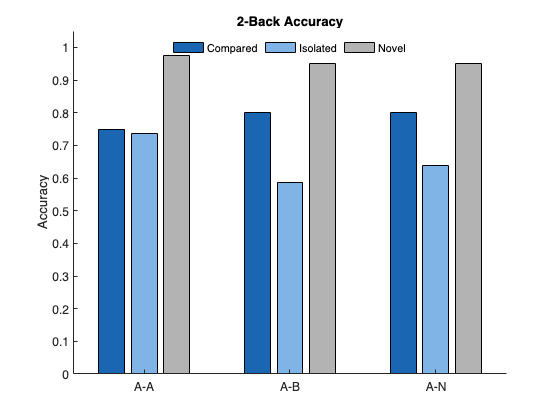

% 2-Back Accuracy
figure('color', 'white');
acc_data = [
    subj_stats.twoback.acc_AA_comp, subj_stats.twoback.acc_AB_comp, subj_stats.twoback.acc_AN_comp;
    subj_stats.twoback.acc_AA_iso,  subj_stats.twoback.acc_AB_iso,  subj_stats.twoback.acc_AN_iso;
    subj_stats.twoback.acc_AA_nov,  subj_stats.twoback.acc_AB_nov,  subj_stats.twoback.acc_AN_nov
];
b1 = bar(acc_data, 'grouped');
b1(1).FaceColor = plot_color_comp;
b1(2).FaceColor = plot_color_iso; 
b1(3).FaceColor = plot_color_nov;

grid off;
box off;
title('2-Back Accuracy', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('Accuracy', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(gca, 'XTickLabel', {'A-A', 'A-B', 'A-N'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
legend({'Compared', 'Isolated', 'Novel'}, 'Location', 'north', ...
    'Orientation', 'horizontal', 'FontName', plot_font_name, 'Box', 'off');
ylim([0, 1.05]);

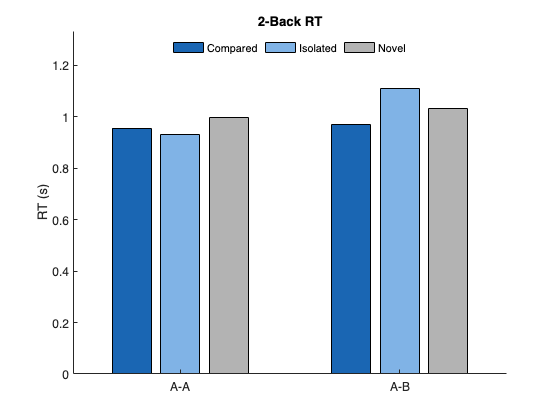


% 2-Back RT
figure('color', 'white');
rt_data = [
    subj_stats.twoback.rt_AA_comp, subj_stats.twoback.rt_AA_iso, subj_stats.twoback.rt_AA_nov;
    subj_stats.twoback.rt_AB_comp, subj_stats.twoback.rt_AB_iso, subj_stats.twoback.rt_AB_nov
];
b2 = bar(rt_data, 'grouped');
b2(1).FaceColor = plot_color_comp;
b2(2).FaceColor = plot_color_iso;
b2(3).FaceColor = plot_color_nov;

grid off;
box off;
title('2-Back RT', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('RT (s)', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(gca, 'XTickLabel', {'A-A', 'A-B'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
legend({'Compared', 'Isolated', 'Novel'}, 'Location', 'north', ...
    'Orientation', 'horizontal', 'FontName', plot_font_name, 'Box', 'off');

if all(~isnan(rt_data(:))), ylim([0, max(rt_data(:)) * 1.2]); end

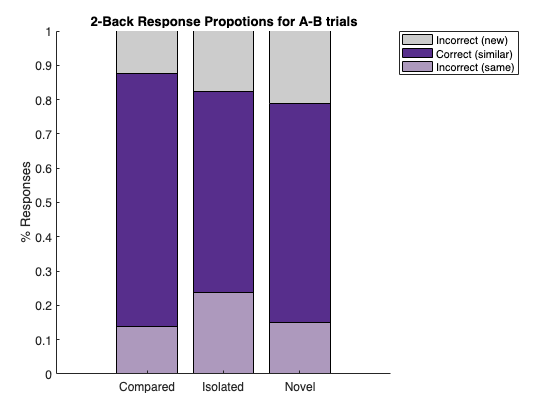

drawnow;

% 2-Back response proportions (A-B trials)
figure('color', 'white');
plot_data_lure = [
    subj_stats.twoback.err_AB_comp_as_j, subj_stats.twoback.acc_AB_comp, subj_stats.twoback.err_AB_comp_as_none;
    subj_stats.twoback.err_AB_iso_as_j,  subj_stats.twoback.acc_AB_iso,  subj_stats.twoback.err_AB_iso_as_none;
    subj_stats.twoback.err_AB_nov_as_j,  subj_stats.twoback.acc_AB_nov,  subj_stats.twoback.err_AB_nov_as_none
];
b_stack = bar(plot_data_lure, 'stacked');
b_stack(1).FaceColor = plot_color_same;    % response 'j'
b_stack(2).FaceColor = plot_color_similar; % response 'k' (correct)
b_stack(3).FaceColor = plot_color_new;     % response 'none'

box off;
grid off;
title('2-Back Response Propotions for A-B trials', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('% Responses', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(gca, 'XTickLabel', {'Compared', 'Isolated', 'Novel'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
legend({'Incorrect (same)', 'Correct (similar)', 'Incorrect (new)'}, 'Location', 'bestoutside', 'FontName', plot_font_name);
ylim([0, 1.0]);

#### 2-Back SDT

% A-A d-prime (A-A vs A-N)
% 'compared'
hr_AA_comp = subj_stats.twoback.acc_AA_comp;
far_AA_comp = subj_stats.twoback.err_AN_comp_as_j;
if hr_AA_comp == 1, hr_AA_comp = 1 - (1 / (2 * n_AA_comp)); end
if hr_AA_comp == 0, hr_AA_comp = 1 / (2 * n_AA_comp); end
if far_AA_comp == 0, far_AA_comp = 1 / (2 * n_AN_comp); end
if far_AA_comp == 1, far_AA_comp = 1 - (1 / (2 * n_AN_comp)); end
subj_stats.twoback.d_AA_comp = norminv(hr_AA_comp) - norminv(far_AA_comp);

% 'isolated'
hr_AA_iso = subj_stats.twoback.acc_AA_iso;
far_AA_iso = subj_stats.twoback.err_AN_iso_as_j;
if hr_AA_iso == 1, hr_AA_iso = 1 - (1 / (2 * n_AA_iso)); end
if hr_AA_iso == 0, hr_AA_iso = 1 / (2 * n_AA_iso); end
if far_AA_iso == 0, far_AA_iso = 1 / (2 * n_AN_iso); end
if far_AA_iso == 1, far_AA_iso = 1 - (1 / (2 * n_AN_iso)); end
subj_stats.twoback.d_AA_iso = norminv(hr_AA_iso) - norminv(far_AA_iso);

% 'novel'
hr_AA_nov = subj_stats.twoback.acc_AA_nov;
far_AA_nov = subj_stats.twoback.err_AN_nov_as_j;
if hr_AA_nov == 1, hr_AA_nov = 1 - (1 / (2 * n_AA_nov)); end
if hr_AA_nov == 0, hr_AA_nov = 1 / (2 * n_AA_nov); end
if far_AA_nov == 0, far_AA_nov = 1 / (2 * n_AN_nov); end
if far_AA_nov == 1, far_AA_nov = 1 - (1 / (2 * n_AN_nov)); end
subj_stats.twoback.d_AA_nov = norminv(hr_AA_nov) - norminv(far_AA_nov);

% A-B d-prime (A-B vs A-N)
% 'compared'
hr_AB_comp = subj_stats.twoback.acc_AB_comp;
far_AB_comp = subj_stats.twoback.err_AN_comp_as_k;
if hr_AB_comp == 1, hr_AB_comp = 1 - (1 / (2 * n_AB_comp)); end
if hr_AB_comp == 0, hr_AB_comp = 1 / (2 * n_AB_comp); end
if far_AB_comp == 0, far_AB_comp = 1 / (2 * n_AN_comp); end
if far_AB_comp == 1, far_AB_comp = 1 - (1 / (2 * n_AN_comp)); end
subj_stats.twoback.d_AB_comp = norminv(hr_AB_comp) - norminv(far_AB_comp);
subj_stats.twoback.ldi_comp = hr_AB_comp - far_AB_comp; % lure discrimination index

% 'isolated'
hr_AB_iso = subj_stats.twoback.acc_AB_iso;
far_AB_iso = subj_stats.twoback.err_AN_iso_as_k;
if hr_AB_iso == 1, hr_AB_iso = 1 - (1 / (2 * n_AB_iso)); end
if hr_AB_iso == 0, hr_AB_iso = 1 / (2 * n_AB_iso); end
if far_AB_iso == 0, far_AB_iso = 1 / (2 * n_AN_iso); end
if far_AB_iso == 1, far_AB_iso = 1 - (1 / (2 * n_AN_iso)); end
subj_stats.twoback.d_AB_iso = norminv(hr_AB_iso) - norminv(far_AB_iso);
subj_stats.twoback.ldi_iso = hr_AB_iso - far_AB_iso; % lure discrimination index

% 'novel'
hr_AB_nov = subj_stats.twoback.acc_AB_nov;
far_AB_nov = subj_stats.twoback.err_AN_nov_as_k;
if hr_AB_nov == 1, hr_AB_nov = 1 - (1 / (2 * n_AB_nov)); end
if hr_AB_nov == 0, hr_AB_nov = 1 / (2 * n_AB_nov); end
if far_AB_nov == 0, far_AB_nov = 1 / (2 * n_AN_nov); end
if far_AB_nov == 1, far_AB_nov = 1 - (1 / (2 * n_AN_nov)); end
subj_stats.twoback.d_AB_nov = norminv(hr_AB_nov) - norminv(far_AB_nov);
subj_stats.twoback.ldi_nov = hr_AB_nov - far_AB_nov; % lure discrimination index

% print d-prime results
fprintf('\n--- 2-Back d-prime Results ---\n');


--- 2-Back d-prime Results ---


fprintf('  d_A-A | Comp: %.3f, Iso: %.3f, Nov: %.3f\n', subj_stats.twoback.d_AA_comp, subj_stats.twoback.d_AA_iso, subj_stats.twoback.d_AA_nov);

  d_A-A | Comp: 2.916, Iso: 2.802, Nov: 2.802


fprintf('  d_A-B | Comp: %.3f, Iso: %.3f, Nov: %.3f\n', subj_stats.twoback.d_AB_comp, subj_stats.twoback.d_AB_iso, subj_stats.twoback.d_AB_nov);

  d_A-B | Comp: 2.596, Iso: 2.181, Nov: 2.312


fprintf('  LDI   | Comp: %.3f, Iso: %.3f, Nov: %.3f\n', subj_stats.twoback.ldi_comp, subj_stats.twoback.ldi_iso, subj_stats.twoback.ldi_nov);

  LDI   | Comp: 0.713, Iso: 0.562, Nov: 0.612


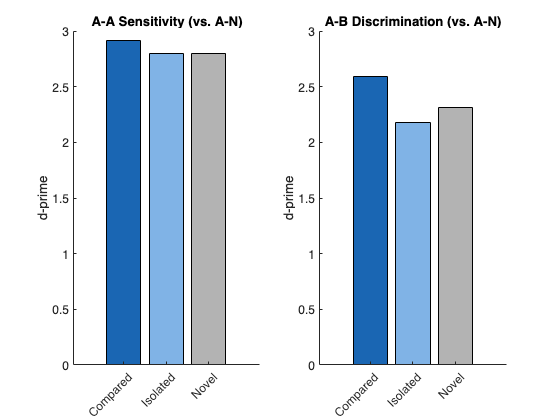

figure('color', 'white');

% plot A-A d-prime
h_ax3 = subplot(1, 2, 1);
d_AA_data = [subj_stats.twoback.d_AA_comp, subj_stats.twoback.d_AA_iso, subj_stats.twoback.d_AA_nov];
b3 = bar(d_AA_data, 'FaceColor', 'flat');
b3.CData(1,:) = plot_color_comp;
b3.CData(2,:) = plot_color_iso;
b3.CData(3,:) = plot_color_nov;
grid of;
box off;
title('A-A Sensitivity (vs. A-N)', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('d-prime', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax3, 'XTickLabel', {'Compared', 'Isolated', 'Novel'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
xtickangle(h_ax3, 45);

% plot A-B d-prime
h_ax4 = subplot(1, 2, 2);
d_AB_data = [subj_stats.twoback.d_AB_comp, subj_stats.twoback.d_AB_iso, subj_stats.twoback.d_AB_nov];
b4 = bar(d_AB_data, 'FaceColor', 'flat');
b4.CData(1,:) = plot_color_comp;
b4.CData(2,:) = plot_color_iso;
b4.CData(3,:) = plot_color_nov;
grid off;
box off;
title('A-B Discrimination (vs. A-N)', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('d-prime', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax4, 'XTickLabel', {'Compared', 'Isolated', 'Novel'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
xtickangle(h_ax4, 45);

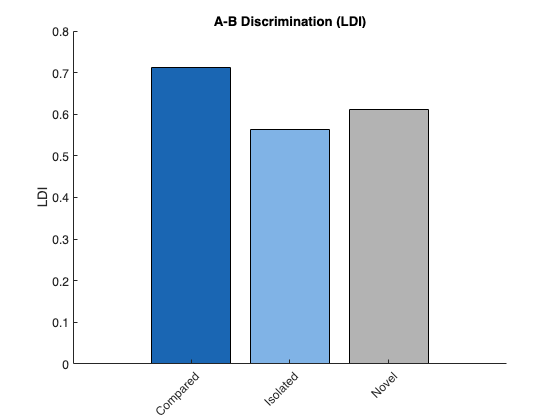

figure('color', 'white');

ldi_data = [subj_stats.twoback.ldi_comp, subj_stats.twoback.ldi_iso, subj_stats.twoback.ldi_nov];
b5 = bar(ldi_data, 'FaceColor', 'flat');
b5.CData(1,:) = plot_color_comp;
b5.CData(2,:) = plot_color_iso;
b5.CData(3,:) = plot_color_nov;
grid off;
box off;
title('A-B Discrimination (LDI)', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('LDI', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(gca, 'XTickLabel', {'Compared', 'Isolated', 'Novel'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);
xtickangle(gca, 45);

## Recognition

### Sanity check

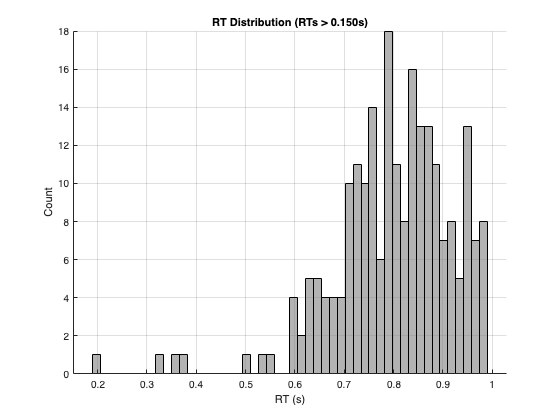

%% code correctness
results_recognition.corr_resp = cellstr(results_recognition.corr_resp);
results_recognition.resp_key = cellstr(results_recognition.resp_key);
resp_idx = ~strcmp(results_recognition.resp_key, 'NA');
num_resp = sum(resp_idx);
num_total = height(results_recognition);
results_recognition.correct = strcmp(results_recognition.corr_resp, results_recognition.resp_key);

% how much did they respond?
subj_stats.recog.per_resp = num_resp / num_total;

% how accurately was their response?
subj_stats.recog.overall_acc = mean(results_recognition.correct(resp_idx));

% how fast did they respond?
valid_rt_idx = results_recognition.rt > MIN_RT_CUTOFF;
all_valid_rts = results_recognition.rt(valid_rt_idx);

figure('color', 'white');
histogram(all_valid_rts, 50, 'FaceColor', [0.5 0.5 0.5]);
title(sprintf('RT Distribution (RTs > %.3fs)', MIN_RT_CUTOFF));
xlabel('RT (s)');
ylabel('Count');
grid on;
box off;


% store rt stats
subj_stats.recog.median_rt = median(all_valid_rts);

% print sanity checks
fprintf('percent responded: %f\n', subj_stats.recog.per_resp);

percent responded: 0.754167


fprintf('overall accuracy: %f\n', subj_stats.recog.overall_acc);

overall accuracy: 0.668508


fprintf('median reaction times: %f\n', subj_stats.recog.median_rt);

median reaction times: 0.808776


### SDT

#### overall hit rate and false alarm rate

old_trials = results_recognition(results_recognition.trial_type == "old", :);
new_trials = results_recognition(results_recognition.trial_type ~= "old", :);
n_old = height(old_trials);
n_new = height(new_trials);
n_hits = sum(old_trials.correct == 1 & old_trials.rt > MIN_RT_CUTOFF);
n_fa = sum(strcmp(new_trials.resp_key, 'j') & new_trials.rt > MIN_RT_CUTOFF);

HR = n_hits / n_old;
FAR = n_fa / n_new;

% correction
if HR == 1, HR = 1 - (1 / (2 * n_old)); end
if HR == 0, HR = 1 / (2 * n_old); end 
if FAR == 0, FAR = 1 / (2 * n_new); end
if FAR == 1, FAR = 1 - (1 / (2 * n_new)); end 

% store overall sdt
subj_stats.recog.HR_overall = HR;
subj_stats.recog.FAR_overall = FAR;
subj_stats.recog.d_prime_overall = norminv(HR) - norminv(FAR);

fprintf('overall hit rate: %f\n', subj_stats.recog.HR_overall);

overall hit rate: 0.366667


fprintf('overall false alarm rate: %f\n', subj_stats.recog.FAR_overall);

overall false alarm rate: 0.108333


fprintf('overall d''prime: %f\n', subj_stats.recog.d_prime_overall);

overall d'prime: 0.894746


#### Compared vs Isolated

comp_trials = old_trials(old_trials.condition == "compared", :);
iso_trials = old_trials(old_trials.condition == "isolated", :);
n_comp = height(comp_trials);
n_iso = height(iso_trials);

% comp hits
n_hits_comp = sum(comp_trials.correct == 1 & comp_trials.rt > MIN_RT_CUTOFF);
HR_comp = n_hits_comp / n_comp;
if HR_comp == 1, HR_comp = 1 - (1 / (2 * n_comp)); end
if HR_comp == 0, HR_comp = 1 / (2 * n_comp); end

% iso hits
n_hits_iso = sum(iso_trials.correct == 1 & iso_trials.rt > MIN_RT_CUTOFF);
HR_iso = n_hits_iso / n_iso;
if HR_iso == 1, HR_iso = 1 - (1 / (2 * n_iso)); end
if HR_iso == 0, HR_iso = 1 / (2 * n_iso); end

% store conditional sdt
subj_stats.recog.HR_comp = HR_comp;
subj_stats.recog.d_prime_comp = norminv(HR_comp) - norminv(FAR);
subj_stats.recog.HR_iso = HR_iso;
subj_stats.recog.d_prime_iso = norminv(HR_iso) - norminv(FAR);

fprintf('compared HR: %f\n', subj_stats.recog.HR_comp);

compared HR: 0.358333


fprintf('compared d prime: %f\n', subj_stats.recog.d_prime_comp);

compared d prime: 0.872523


fprintf('isolated HR: %f\n', subj_stats.recog.HR_iso);

isolated HR: 0.375000


fprintf('isolated d prime: %f\n', subj_stats.recog.d_prime_iso);

isolated d prime: 0.916801


### A vs B

A_trials = old_trials(old_trials.identity == "A", :);
B_trials = old_trials(old_trials.identity == "B", :);
n_A = height(A_trials);
n_B = height(B_trials);

% A its
n_hits_A = sum(A_trials.correct == 1 & A_trials.rt > MIN_RT_CUTOFF);
HR_A = n_hits_A / n_A;
if HR_A == 1, HR_A = 1 - (1 / (2 * n_A)); end
if HR_A == 0, HR_A = 1 / (2 * n_A); end

% B hits
n_hits_B = sum(B_trials.correct == 1 & B_trials.rt > MIN_RT_CUTOFF);
HR_B = n_hits_B / n_B;
if HR_B == 1, HR_B = 1 - (1 / (2 * n_B)); end
if HR_B == 0, HR_B = 1 / (2 * n_B); end

% storee A vs B sdt
subj_stats.recog.HR_A = HR_A;
subj_stats.recog.d_prime_A = norminv(HR_A) - norminv(FAR);
subj_stats.recog.HR_B = HR_B;
subj_stats.recog.d_prime_B = norminv(HR_B) - norminv(FAR);

fprintf('A HR: %f\n', subj_stats.recog.HR_A);

A HR: 0.371212


fprintf('A d prime: %f\n', subj_stats.recog.d_prime_A);

A d prime: 0.906796


fprintf('B HR: %f\n', subj_stats.recog.HR_B);

B HR: 0.361111


fprintf('B d prime: %f\n', subj_stats.recog.d_prime_B);

B d prime: 0.879950


### RT

#### Compared vs Isolated vs Foil

rt_comp_hits = mean(results_recognition.rt(...
    results_recognition.condition == "compared" & ...
    results_recognition.correct == 1 & valid_rt_idx), 'omitnan');

rt_iso_hits = mean(results_recognition.rt(...
    results_recognition.condition == "isolated" & ...
    results_recognition.correct == 1 & valid_rt_idx), 'omitnan');

rt_new_crs = mean(results_recognition.rt(...
    results_recognition.trial_type ~= "old" & ...
    results_recognition.correct == 1 & valid_rt_idx), 'omitnan');

% by item identity
rt_A_hits = mean(results_recognition.rt(...
    results_recognition.identity == "A" & ...
    results_recognition.correct == 1 & valid_rt_idx), 'omitnan');
    
rt_B_hits = mean(results_recognition.rt(...
    results_recognition.identity == "B" & ...
    results_recognition.correct == 1 & valid_rt_idx), 'omitnan');

% store rt
subj_stats.recog.rt_comp_hit = rt_comp_hits;
subj_stats.recog.rt_iso_hit = rt_iso_hits;
subj_stats.recog.rt_new_cr = rt_new_crs;
subj_stats.recog.rt_A_hit = rt_A_hits;
subj_stats.recog.rt_B_hit = rt_B_hits;

fprintf('RT compared hit: %f\n', subj_stats.recog.rt_comp_hit);

RT compared hit: 0.801919


fprintf('RT isolated hit: %f\n', subj_stats.recog.rt_iso_hit);

RT isolated hit: 0.806386


fprintf('RT new CR: %f\n', subj_stats.recog.rt_new_cr);

RT new CR: 0.800915


fprintf('RT A hit: %f\n', subj_stats.recog.rt_A_hit);

RT A hit: 0.795913


fprintf('RT B hit: %f\n', subj_stats.recog.rt_B_hit);

RT B hit: 0.814620


### plots: sdt

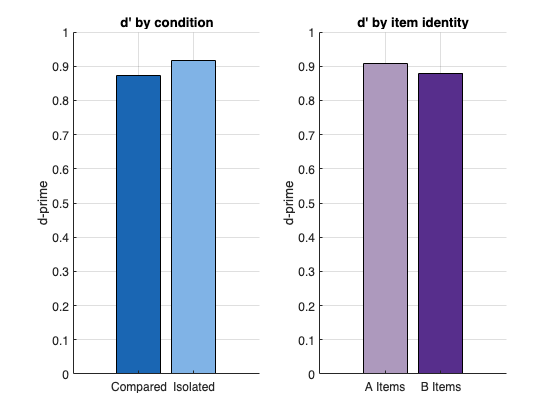

figure('color', 'white'); 

% d' by condition
h_ax1 = subplot(1, 2, 1); 
d_prime_data = [subj_stats.recog.d_prime_comp, subj_stats.recog.d_prime_iso];
b1 = bar(d_prime_data, 'FaceColor', 'flat');
b1.CData(1,:) = plot_color_comp;
b1.CData(2,:) = plot_color_iso;

grid on;
box off;
title('d'' by condition', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('d-prime', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax1, 'XTickLabel', {'Compared', 'Isolated'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);

% d' by item identity
h_ax2 = subplot(1, 2, 2);
d_prime_AB_data = [subj_stats.recog.d_prime_A, subj_stats.recog.d_prime_B];
b2 = bar(d_prime_AB_data, 'FaceColor', 'flat');
b2.CData(1,:) = plot_color_a;
b2.CData(2,:) = plot_color_b;

grid on;
box off;
title('d'' by item identity', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('d-prime', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax2, 'XTickLabel', {'A Items', 'B Items'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);

% HR vs FAR
figure('Color', 'white');
hr_data = [subj_stats.recog.HR_comp, subj_stats.recog.HR_iso];
b3 = bar(hr_data, 'FaceColor', 'flat');
b3.CData(1,:) = plot_color_comp;
b3.CData(2,:) = plot_color_iso;
hold on;
h_far = plot(xlim, [subj_stats.recog.FAR_overall, subj_stats.recog.FAR_overall], ...
    'Color', plot_color_far, 'LineStyle', '--', 'LineWidth', 2);

grid off;
box off;
title('HR vs. FAR', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('Rate', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(gca, 'XTickLabel', {'Compared HR', 'Isolated HR'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);

legend([b3, h_far], {'HR', 'FAR'}, 'Location', 'best', 'FontName', plot_font_name);
ylim([0, 1.0]);

### plots: rt

figure('color', 'white');
h_ax3 = subplot(1, 2, 1);
rt_condition_data = [subj_stats.recog.rt_comp_hit, subj_stats.recog.rt_iso_hit, subj_stats.recog.rt_new_cr];
b4 = bar(rt_condition_data, 'FaceColor', 'flat');
b4.CData(1,:) = plot_color_comp;
b4.CData(2,:) = plot_color_iso;
b4.CData(3,:) = [0.5 0.5 0.5];

grid on;
box off;
title('RT by condition (correct)', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('RT (s)', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax3, 'XTickLabel', {'Compared Hit', 'Isolated Hit', 'New CR'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);

h_ax4 = subplot(1, 2, 2);
rt_identity_data = [subj_stats.recog.rt_A_hit, subj_stats.recog.rt_B_hit];
b5 = bar(rt_identity_data, 'FaceColor', 'flat');
b5.CData(1,:) = plot_color_a;
b5.CData(2,:) = plot_color_b;

grid on;
box off;
title('RT by item identity (correct)', 'FontSize', plot_font_size_title, 'FontName', plot_font_name);
ylabel('RT(s)', 'FontSize', plot_font_size_axis, 'FontName', plot_font_name);
set(h_ax4, 'XTickLabel', {'A Items', 'B Items'}, 'FontName', plot_font_name, 'FontSize', plot_font_size_axis);

### save results

save_file = fullfile(results_dir, sprintf('subj_%03d_stats.mat', subj_id));
save(save_file, 'subj_stats');